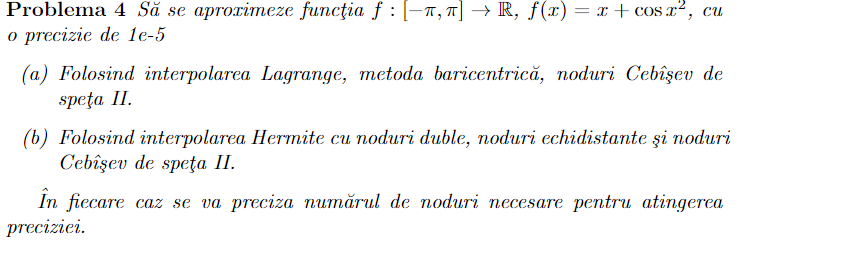

% a)
err = 1e-5;
f=@(x) x + cos(x.^2);

% noduri Cebisev de speta II

xi = linspace(-pi, pi, 100000);
yi = f(xi);
m = 2;

while 1   
    x = nodesCheb(m, -pi, pi);
    y = f(x);
    w = weightsCheb(m);
    cxi = baryLagrange(x, y, xi, w);
    if max(abs(cxi - yi)) < err
        break;
    end
    m = m + 1;
end

% noduri necesare atingerii preciziei
m

m = 26

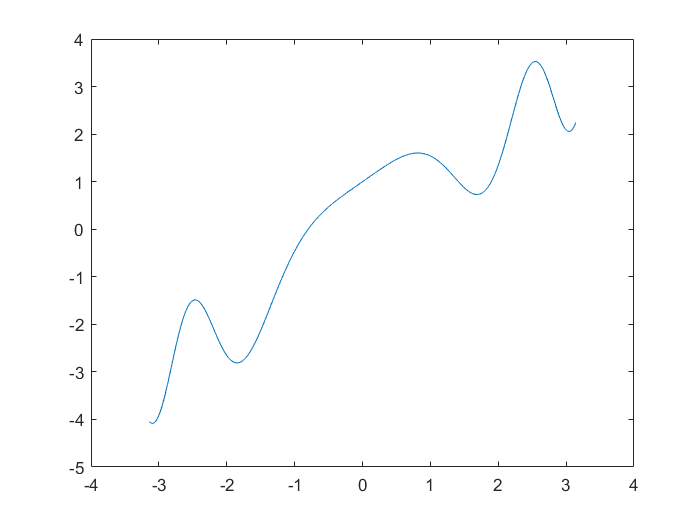

plot(xi, cxi) 

% b)
% chebisev de speta 2
syms x
df=@(x) 1 - 2.*x.*sin(x.^2);
xi = linspace(-pi, pi, 10000);
yi = f(xi);

m = 2;

while 1
  x = nodesCheb(m, -pi, pi);
  cxi =  Hermite(x, f(x), df(x), xi);
  if max(abs(cxi - yi)) < err
      break;
  end
  m = m + 1;
end

% noduri necesare atingerii preciziei
m

m = 13

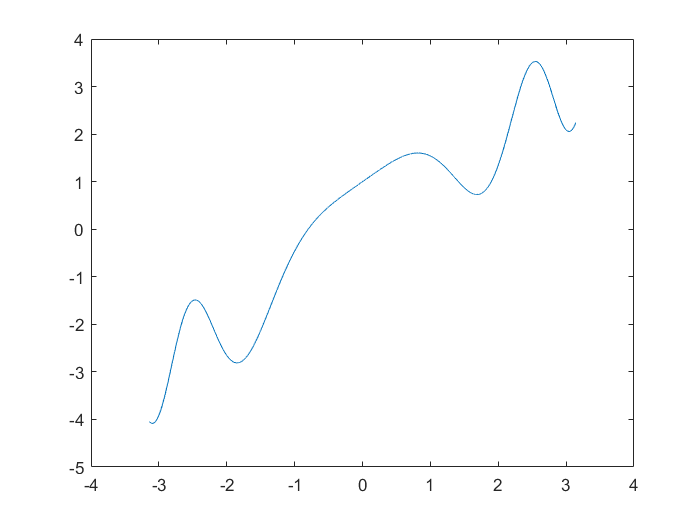


plot(xi, cxi) 

% noduri echidistante
df=@(x) 1 - 2.*x.*sin(x.^2);
xi = linspace(-pi, pi, 10000);
yi = f(xi);
ydi = df(xi);

m = 2;

while 1
  x = linspace(-pi, pi, m);
  cxi =  Hermite(x, f(x), df(x), xi);
  if max(abs(cxi - yi)) < err
      break;
  end
  m = m + 1;
end

% noduri necesare atingerii preciziei
m

m = 19

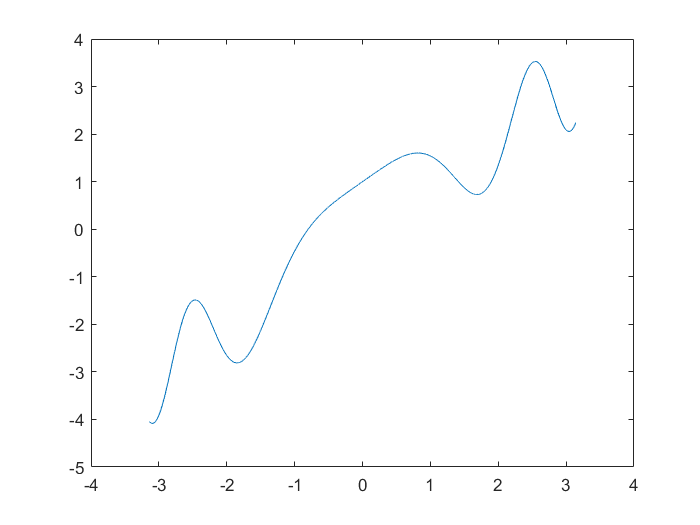


plot(xi, cxi) 